%This code classifies the data obtained by using 64 and Features.
%The code consists of confusion matrices and other performance metrices.
clear;
clc;
close all;

load dataset.mat

%Performance Metrices.
accuracy=[ ];
precision= [ ];
recall=[ ];
f1= [ ];

%Load the Dataset features and Targets.
x_104=data(:,1:104);
y_104=data(:,105);
classes=data(1:330,105);

%Load the Dataset features and Targets.
x_64=data(:,1:64);
y_64=data(:,105);

%Minimum Redundacy Maximum Relevance Algorithm (MRMR)
[idx,scores]=fscmrmr(x_104,y_104);

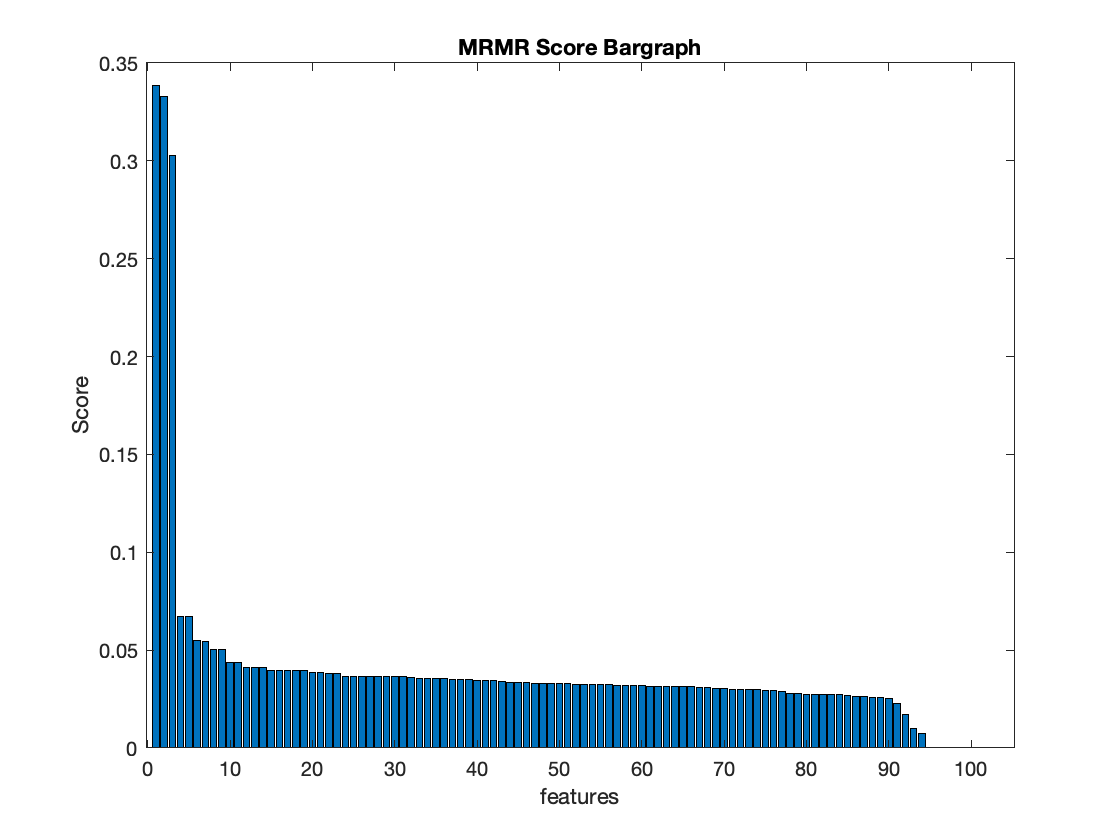


%Plotting the bargraph to check the relevency of the features.
x_mrmr=x_104(:,idx(1:20));
y_mrmr=y_104;

figure;
bar(scores(idx));
xlabel('features');
ylabel('Score');
title('MRMR Score Bargraph');

**Classification:** This code compares the accuracies of three classification algorithms viz, Support Vector Machines (SVM), k-Nearest Neighbours (k-NN) and Bagged Trees.

**Cases:** The classification is performed under three cases.

**Case-1:** 64 features

**Case-2:** 104 Features

**Case-3: **10 Features from Principal Component Analysis (PCA)

**Case-4: **20 Features using MRMR

%SVM
warning('off', 'stats:pca:ColRankDefX')
[~,accuracy(1,1)]=SVM_64(x_64,y_64);
[~,accuracy(1,2)]=SVM_104(x_104,y_104);
[~,accuracy(1,3)]=SVM_PCA(x_64,y_64);
[~,accuracy(1,4)]=SVM_MRMR(x_mrmr,y_mrmr);

%k-NN
[~,accuracy(2,1)]=KNN_64(x_64,y_64);
[~,accuracy(2,2)]=kNN_104(x_104,y_104);
[~,accuracy(2,3)]=KNN_PCA(x_64,y_64);
[~,accuracy(2,4)]=kNN_MRMR(x_mrmr,y_mrmr);

%Bagged Trees.
[~,accuracy(3,1)]=Bagged_Trees_64(x_64,y_64);
[~,accuracy(3,2)]=Bagged_Trees_104(x_104,y_104);
[~,accuracy(3,3)]=Bagged_Trees_PCA(x_64,y_64);
[~,accuracy(3,4)]=Bagged_Tree_MRMR(x_mrmr,y_mrmr);

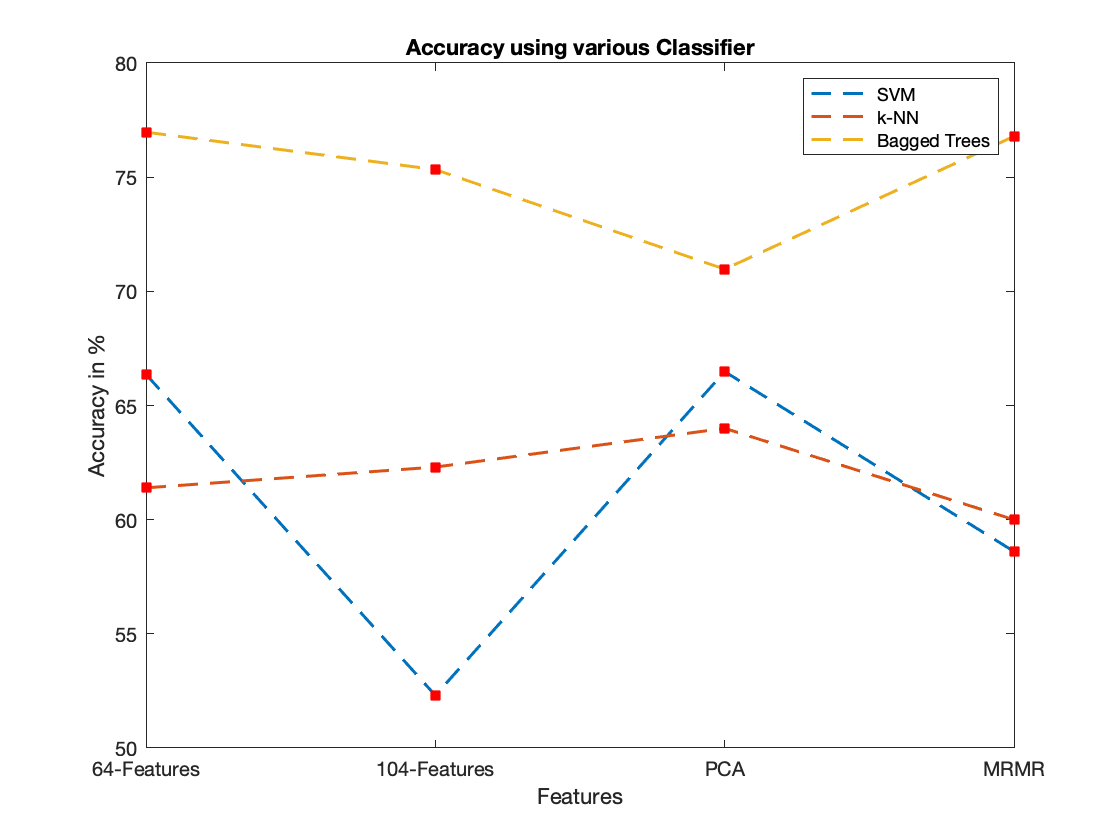

figure;
plot(accuracy'*100,'--','LineWidth',1.5);
hold on;
h=plot(accuracy'*100,'rs');
set(h,'MarkerFaceColor',[1 0 0]);
labels={'64-Features','104-Features','PCA','MRMR'};
xticks([1 2 3 4]);
xticklabels(labels);
xlabel('Features');
ylabel('Accuracy in %');
title('Accuracy using various Classifier');
legend('SVM','k-NN','Bagged Trees');
hold off;

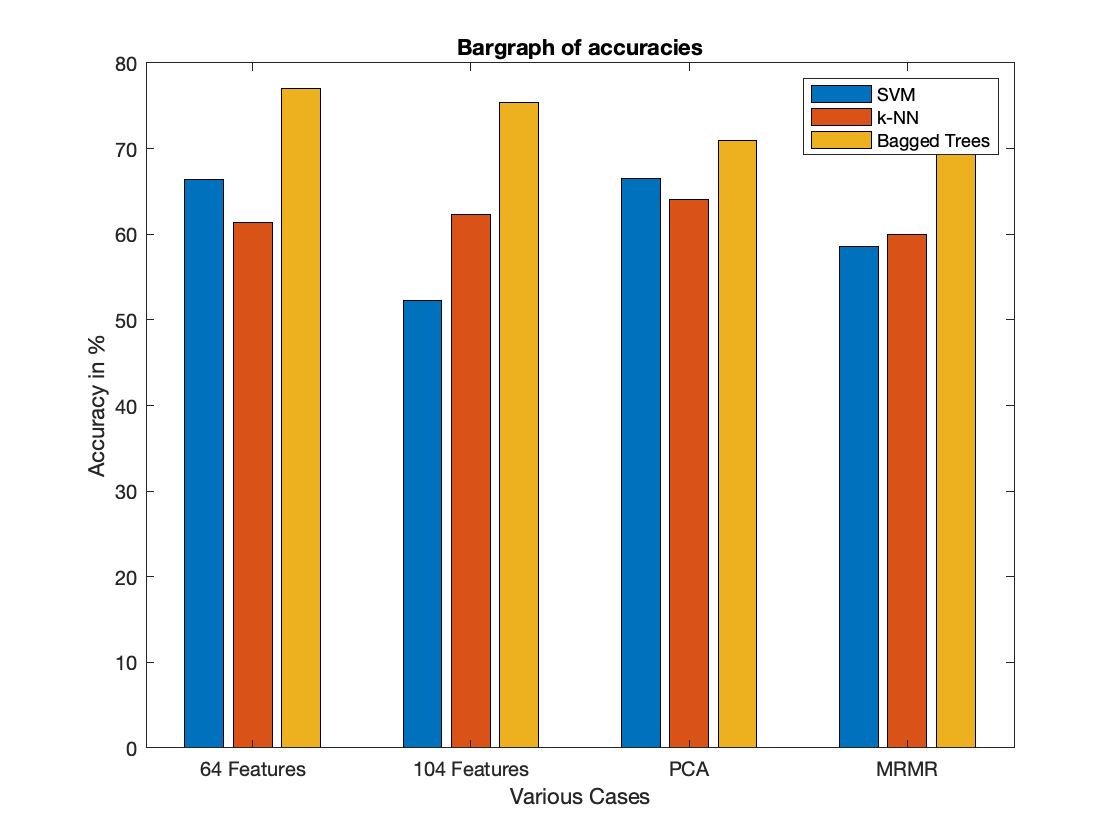


figure;
bar(accuracy'*100);
title('Bargraph of accuracies');
xticklabels({'64 Features','104 Features','PCA','MRMR'});
xlabel('Various Cases');
ylabel('Accuracy in %');
legend('SVM','k-NN','Bagged Trees');